%%%%%%%%%%%%%%%%pep.m
% Resuelve un problema de ramsey con capital humano  y capital fisico,
% descrito en la PEP para Macro 1 (Maestria)
% Esta versi�n esta incompleta!
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%parametros
dk = .1;
dh = .2;
beta = .95;
b = .5;
A = 1;
alfa = 0.3;
alpha = alfa;
gamma= .3;
g= 1.02;

%%%%%ELEMENTO DE ITERACION
fi1= fi_sol(1:6)

fi1 =     2.8793    1.2400   -0.0122    3.8603    0.0231    0.0138


fi2= fi_sol(7:12)

fi2 =    -0.8954    0.0011   -0.0003    1.4358   -0.3490    0.0017


%%%%%%%%%%%%%%

% definimos las variables i_h, c, lambda (mult de la Rest de recursos) y mu
% (mult. de la ley de movimiento de h) de forma secuencial, usando las CPO
i_h = @(y,yp) (1/b)*(yp - (1 - dh)*y).^2 ;%y representa h, hp a h(t+1)
c = @(x,xp,y,yp) (x.^alfa.*y.^gamma +(1-dk)*x -g .* xp-i_h(y,yp));
lambda = @(x,xp,y,yp) (c(x,xp,y,yp)).^(-1);

% Definimos las CPO para k_{t+1} y h_{t+1}
euler_k = @(x,xp,xpp,y,yp,ypp) - g*lambda(x,xp,y,yp) +  beta * lambda(xp,xpp,yp,ypp) .* (1 - dk + alpha * A *xp.^(alfa - 1) .* yp.^(gamma));

euler_h = @(x,xp,xpp,y,yp,ypp) -g*lambda(x,xp,y,yp) + beta*lambda(xp,xpp,yp,ypp)*((1-dh) .*(sqrt(i_h(yp,ypp)/i_h(y,yp)))+b/(2*sqrt(i_h(y,yp))).*(gamma * A *xp.^(alfa) .* yp.^(gamma-1)))

euler_h = function_handle with value:
    @(x,xp,xpp,y,yp,ypp)-g*lambda(x,xp,y,yp)+beta*lambda(xp,xpp,yp,ypp)*((1-dh).*(sqrt(i_h(yp,ypp)/i_h(y,yp)))+b/(2*sqrt(i_h(y,yp))).*(gamma*A*xp.^(alfa).*yp.^(gamma-1)))





%Definimos  las funciones de politica para h_{t+1} y k_{t+1}
kprima = @(k,h, fi1) fi1(1) + fi1(2)* k + fi1(3)*k.^2 + fi1(4)* h ...
    + fi1(5) * h.^2 + fi1(6) * (h .* k)  ;
hprima = @(k,h, fi2) fi2(1) + fi2(2)* k + fi2(3)*k.^2 + fi2(4)* h ...
    + fi2(5) * h.^2 + fi2(6) * (h .* k)  ;

%Sustituimos (dos veces) las funciones de politica en las ecuaciones de
%euler

euler_k2 = @(x,xp,y,yp,fi1,fi2) euler_k(x,xp,kprima(xp,yp,fi1),y,yp, hprima(xp,yp,fi2));
euler_h2 = @(x,xp,y,yp,fi1,fi2) euler_h(x,xp,kprima(xp,yp,fi1),y,yp, hprima(xp,yp,fi2));

euler_k3 = @(x,y,fi1,fi2) euler_k2(x,kprima(x,y,fi1),y,hprima(x,y,fi2),fi1,fi2);
euler_h3 = @(x,y,fi1,fi2) euler_h2(x,kprima(x,y,fi1),y,hprima(x,y,fi2),fi1,fi2);

%Estado estacionario, usando las ecuaciones de euler
euler_ss = @(v) sum(euler_k(v(1),v(1),v(1),v(2),v(2),v(2)))^2 + (euler_h(v(1),v(1),v(1),v(2),v(2),v(2)))^2;

v0 = [3 1.2];
[ss_sol,fval,exitflag] = fminsearch(euler_ss,v0);
if exitflag == 1
    kss = ss_sol( end, 1)
    hss = ss_sol( end, 2)
else
   msg = 'Error occurred.';
   error(msg)
end

kss = 2.3072

hss = 1.1376

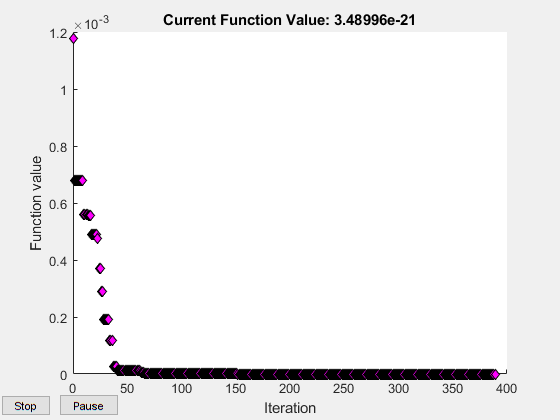

fi_sol =     2.3072    1.1376   -0.0123    4.0694    0.0239    0.0160   -0.8690    0.0014   -0.0004    1.5960   -0.2733    0.0019


fval2 = 3.4900e-21

exitflag = 1


% grilla para k_t y h_t, alrededor del estado estacionario

gridk = [kss*.8 :0.01:kss*1.2];
gridh = [hss*.8 :0.01:hss*1.2];
[gk2d, gh2d] = meshgrid(gridk,gridh) ;           %generate 2 dimensional grid for k and h
%sumamos los erores - definimos fi = [fi1 fi2]
euler_error_k = @(fi) sum(sum((euler_k3(gk2d,gh2d,fi(1:6),fi(7:12))).^2))/numel(gk2d);
euler_error_h = @(fi) sum(sum((euler_h3(gk2d,gh2d,fi(1:6),fi(7:12))).^2))/numel(gh2d);
euler_error = @(fi) euler_error_k(fi) + euler_error_h(fi);

%Obtenemos el vector fi que minimiza la suma de errores
x0 = [    1.8282    1.1264   -0.0114    3.8758    0.0256    0.0162   -0.8832   0.0014   -0.0004    1.9349   -0.2896    0.0019];

%fminsearch
options = optimset('PlotFcns','optimplotfval','TolX',1e-8);    
[fi_sol,fval2,exitflag] = fminsearch(euler_ss,x0, options)

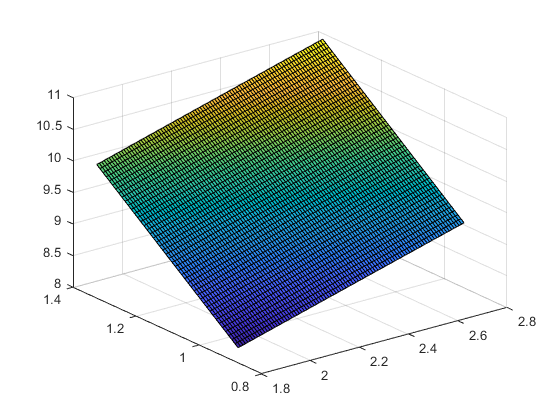

 
%graficos
pfk = kprima(gk2d,gh2d,fi_sol(1:6));
pfh = hprima(gk2d,gh2d,fi_sol(7:12));
figure(1)
surf(gk2d,gh2d,pfk);

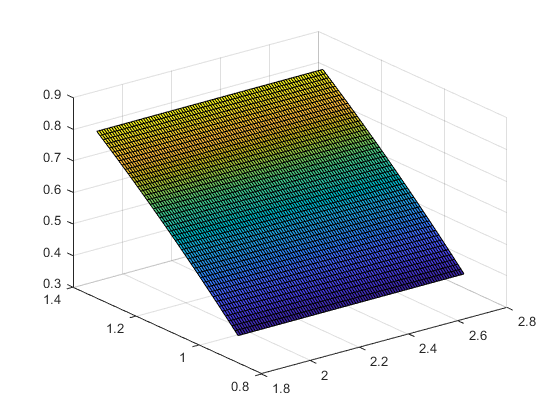

figure(2)
surf(gk2d,gh2d,pfh);



ss_sol

ss_sol =     2.3072    1.1376


fi_sol

fi_sol =     2.3072    1.1376   -0.0123    4.0694    0.0239    0.0160   -0.8690    0.0014   -0.0004    1.5960   -0.2733    0.0019
